## Water Resources Engineering  Assignment Group XX

## Hydrological model. 

*Implement the hydrological model on the 6-year-long series of precipitation and discharge.*

clear 
close

%% Load data
load area_rating_curve.txt
load kc.txt % [-]
load P.txt % [mm/h]
load Q_obs.txt %[m^3/s]
load temperature.txt

Nyears=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7;        %[m^3/s] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000;       %[km^2] Catchment area
phi = 38;       %[°] Latitude 

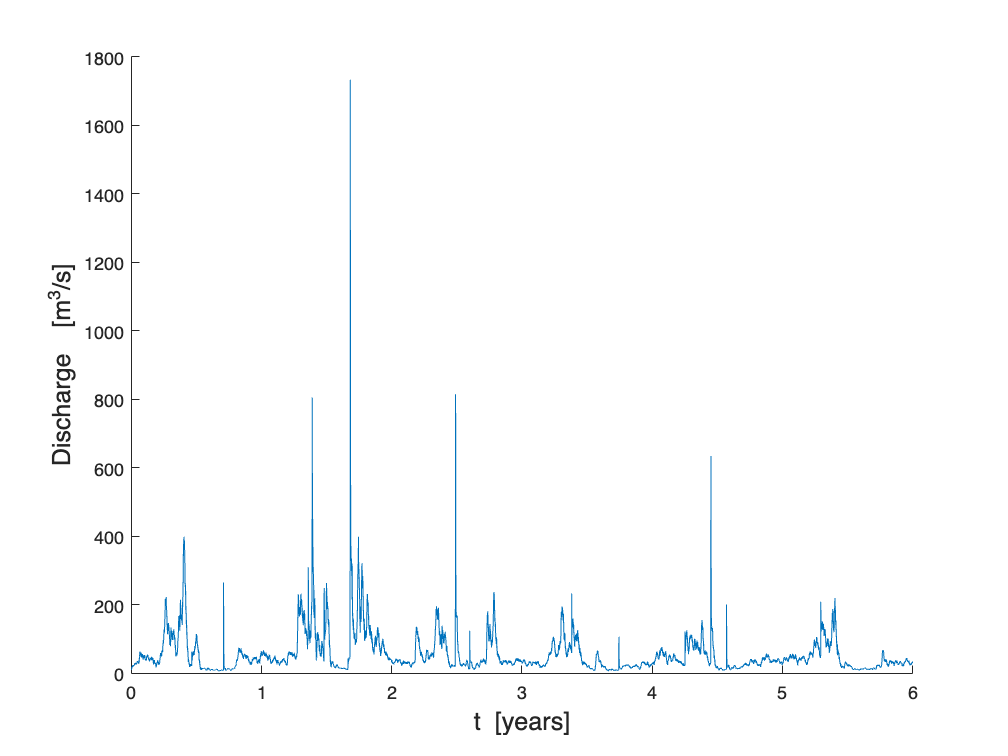

%% Plot discharge time series
figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

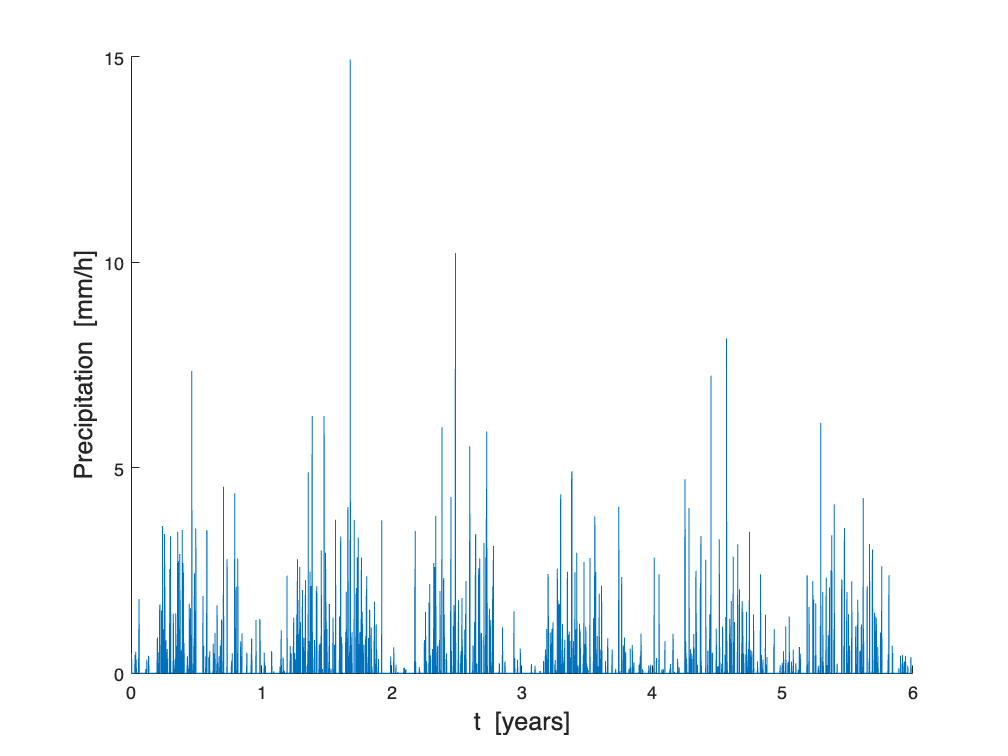


%% Plot precipitation time series
figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [mm/h]','FONTSIZE',14)   %insert label y axis
box off

### 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) through the Thornthwaite equation 

I = sum((temperature./5).^(1.514));
a = 6.75*(10^(-7))*(I^3) - 7.71*(10^(-5))*(I^2) + 1.79*(10^(-2))*I + 0.49; %experimental exponent
D = 1:365;
delt = 0.409*sin(2*pi*D/365-1.39);
w_s = acos(-tan(phi*pi/180)*tan(delt));
N_D = 24*w_s/pi; %number of daylight hours of day D
N_M =zeros(12,1); % mean daylight hours per day of month m


for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = ((16.*(N_M/12).*(10*temperature/I).^a)/24)./day_month'; % [mm/h/unit area]


### 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.

% Hydrological model: to be calibrated

K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 [mm/h]
c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
delta = [K_sat, c, z, t_sub];

% K_sat = 23.1423
% c = 16.4239
% z = 628.5144
% t_sub = 329.4774

### 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale

% Settings
s = zeros(length(Q_obs),1);     % saturation vector
s(1) = 0.5;                     % initial arbitrary value

Vsup = zeros(length(Q_obs),1);  % superficial stored volume vector

Vsub = zeros(length(Q_obs),1);  % sub-superficial stored volume vector

N_hours_per_year = 365*24;      %number of hours per year
ET = zeros(length(Q_obs),1); 
L = zeros(length(Q_obs),1);

% Infiltration
K_sat_vect = ones(length(P),1)*K_sat;  % K_sat vector to compare with precipitation
I = min(P,K_sat_vect); %[mm/h]

% Runoff
R = P-I; %[mm/h]

for y=1:Nyears
    for m=1:12
        for h=month_start_hour(m):month_end_hour(m)
            t=(y-1)*N_hours_per_year+h; 
            if s(t)<=sw && s(t)>=0
                ET(t)= 0;
            elseif s(t)<=s1 && s(t)>sw
                ET(t)= kc(m)*ET_0(m)*((s(t)-sw)/(s1-sw));
            elseif s(t)<=1 && s(t)>s1
                ET(t)= kc(m)*ET_0(m);
            elseif s(t)>1
                    disp('Warning : s > 1')
            elseif s(t)<0
                    disp('Warning : s < 0')
            end
            L(t)=K_sat*(s(t)^c);
            s(t+1)=s(t)+((I(t)-ET(t)-L(t))*(1/(n*z)));
            Vsup(t+1)=Vsup(t)+R(t)-((t_sup^(-1))*Vsup(t));
            Vsub(t+1)=Vsub(t)+L(t)-((t_sub^(-1))*Vsub(t));
        end
    end
end


qsup=Vsup/t_sup;
qsub=Vsub/t_sub;
Qsup=A*qsup/3.6;
Qsub=A*qsub/3.6;

### 4. Test the mass balance of your system in order to ensure a correct implementation.

doTest=1;
dt=1;

%compute total discharge Q
if doTest % if doTest=1, check mass balance
    P_tot=sum(P)*dt;
    R_tot=sum(R)*dt;
    L_tot=sum(L)*dt;
    ET_tot=sum(ET)*dt;
    %"testS" balance for the root zone (input/output). testS = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testS=P_tot/(ET_tot+R_tot+L_tot+n*z*(s(end)-s(1)))

    %"testQ" balance for the whole system (input/output). testQ = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testQ=sum(P-ET)/(sum(qsup+qsub)+n*z*(s(end)-s(1))+Vsup(end)+Vsub(end))
end

testS = 1.0000

testQ = 1.0000

### 5. Evaluate the goodness of fit of the chosen parameter set by calculating the Nash-Sutcliffe index NS.

Q_mod = Qsub+Qsup+Q_b;
Q_mod = Q_mod(1:52560,1);

NS = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS = 0.4609


%(P, ET_0, kc, K_sat, c, t_sub, t_sup, z, sw, s1, n, Q_b, A,doTest)
[Q_mod, R, I] = hydrological_model(P, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A, 1);

testS = 1.0000

testQ = 1.0000

Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS_old = -3.2538

## Model calibration

Find the set of parameters {Ksat, c, tsub, z} that maximizes the Nash-Sutcliffe index. Use a simulated annealing strategy in order to find the parameter set that maximizes NS.

### 1. Define a functional form for the temperature

### 2. Attribute arbitrary values to the parameters Ksat, c, tsub, z. Run the hydrological model and evaluate NSold.

% K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5 
% c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
% z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
% t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
% 
% delta = [K_sat, c, z, t_sub];

ranges = [0.99e-05*(3.6e6),19,1999,399];
upper_lim = [1e-5*(3.6e6),20,2000,400];
lower_lim = [1e-7*(3.6e6),1,1,1];
sigma = 5/100;
cr = 1/1200;

[Q_mod, R, I] = hydrological_model(P, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A, 1);

testS = 1.0000

testQ = 1.0000

Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS_old = -3.2538

### 3. Select a new parameter set by drawing from a truncated normal distribution centered in the previous parameter set (use function TruncNormRnd.m)

delta_old=delta;
delta_new=delta;
ls = [];
T_SA = [];
NS = [];

Niter=1000;
niter = 1 ; 
ii = 0;
while niter<Niter
    for i=1:length(delta)
        delta_new(i)=TruncNormRnd(delta_old(i),sigma*delta_old(i),lower_lim(i),upper_lim(i));
    end
    [Q_mod, R_out, I_out] = hydrological_model(P, ET_0, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A, 1);
    Q_mod = Q_mod(1:52560,1);
    NS_new = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)));
    
    if NS_new>NS_old
        delta_old = delta_new;
        NS_old = NS_new;
        ii = ii +1 ;
        ls(ii,:) = delta_new;
        T_SA(ii) = t_sa(cr, niter);
        NS(ii) = NS_old;
        
    else
        r = rand;
        if r<exp((NS_new-NS_old)/t_sa(cr,niter))
            NS_old = NS_new;
        end
    end
    if NS_new >=0.85
        break
    end
    
    niter=niter+1;
end

here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here
here


## ** Deliverables 1 and 2**

**New set of best fit parameters for the hydrological model**

disp(['ksat = ', num2str(delta_new(1)), ' ; c_new = ', num2str(delta_new(2)), ' ; z_new = ', num2str(delta_new(3)), ' ; t_sub_new = ', num2str(delta_new(4))])

ksat = 4.8119 ; c_new = 10.466 ; z_new = 1914.9417 ; t_sub_new = 97.0884


**Plot the time series (6-year-long) of precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the given precipitation).**

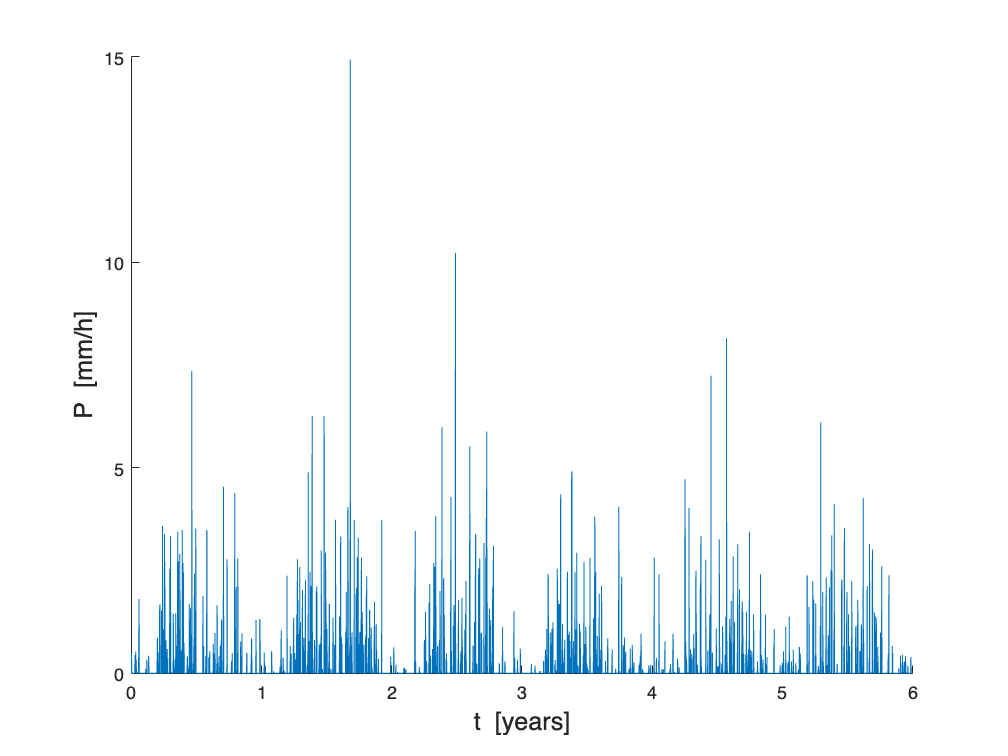

figure(3)                                          
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('P  [mm/h]','FONTSIZE',14)   
box off

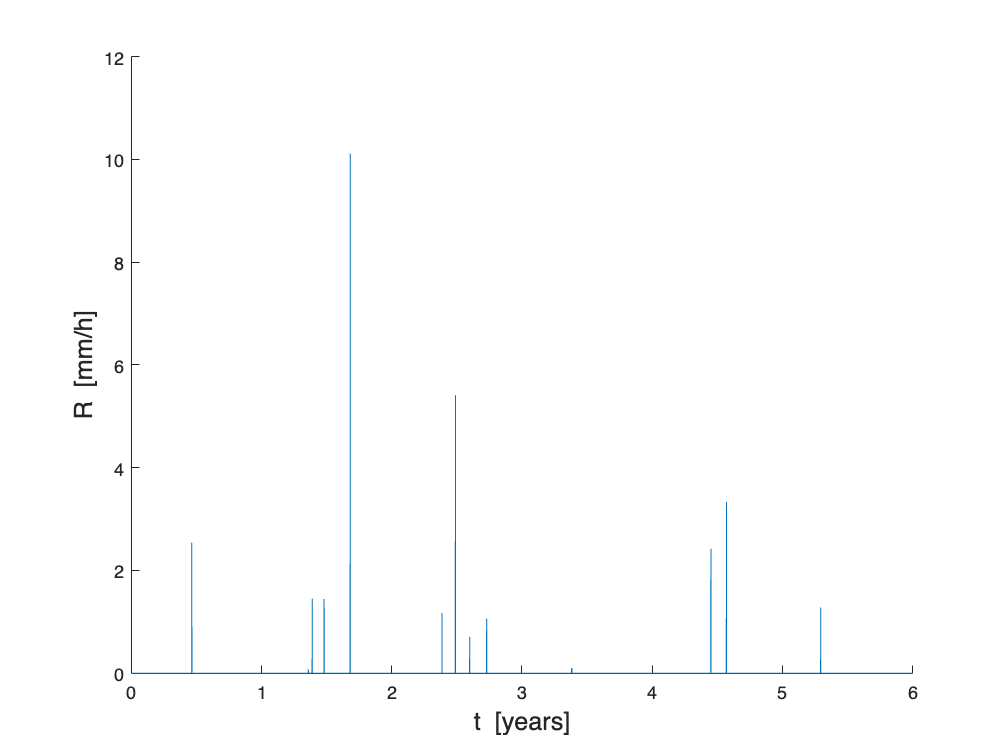

figure(4)                                          
plot((1:length(R_out))/(365*24),R_out);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('R  [mm/h]','FONTSIZE',14)   
box off

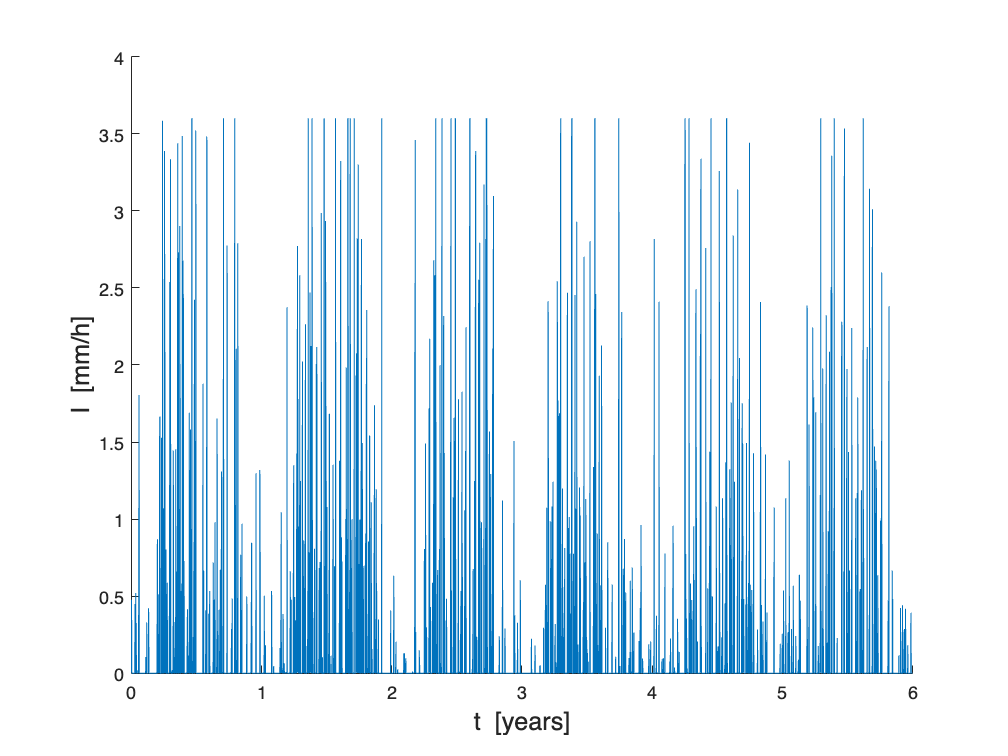


figure(5)                                          
plot((1:length(I))/(365*24),I);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('I  [mm/h]','FONTSIZE',14)   
box off

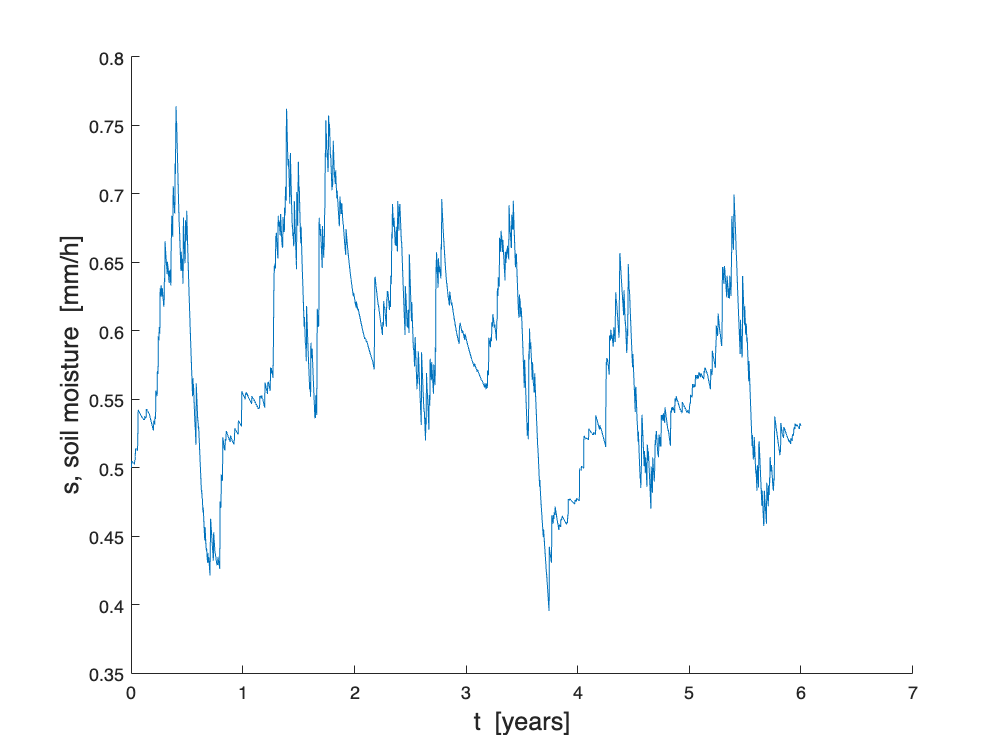

figure(6)                                          
plot((1:length(s))/(365*24),s);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('s, soil moisture  [mm/h]','FONTSIZE',14)   
box off

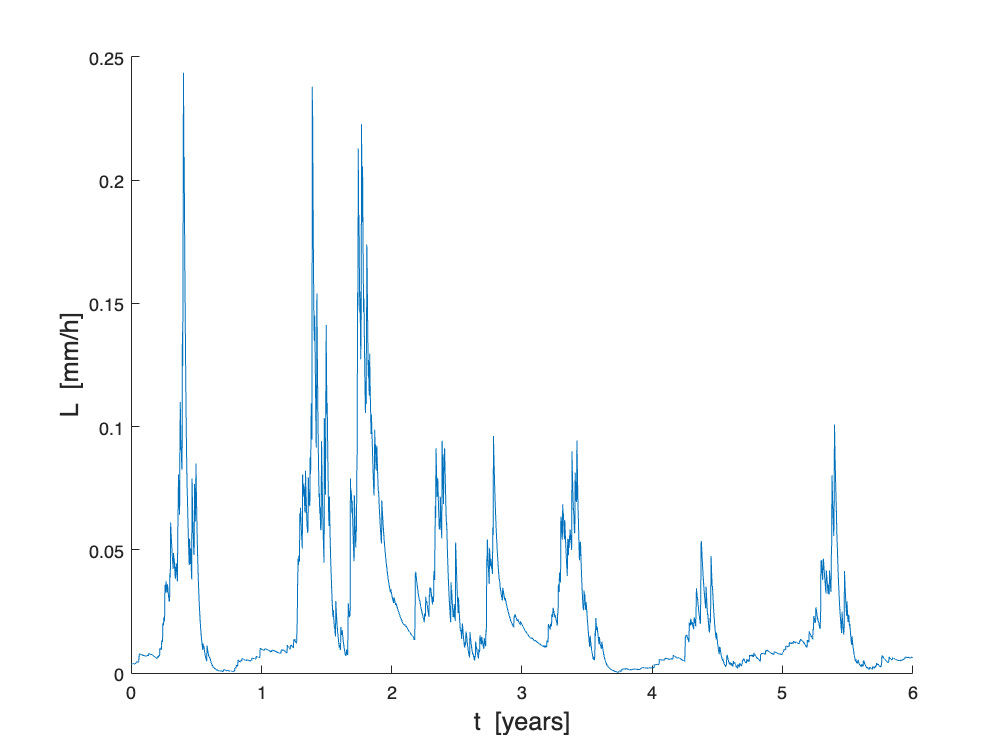

figure(7)                                          
plot((1:length(L))/(365*24),L);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('L  [mm/h]','FONTSIZE',14)   
box off

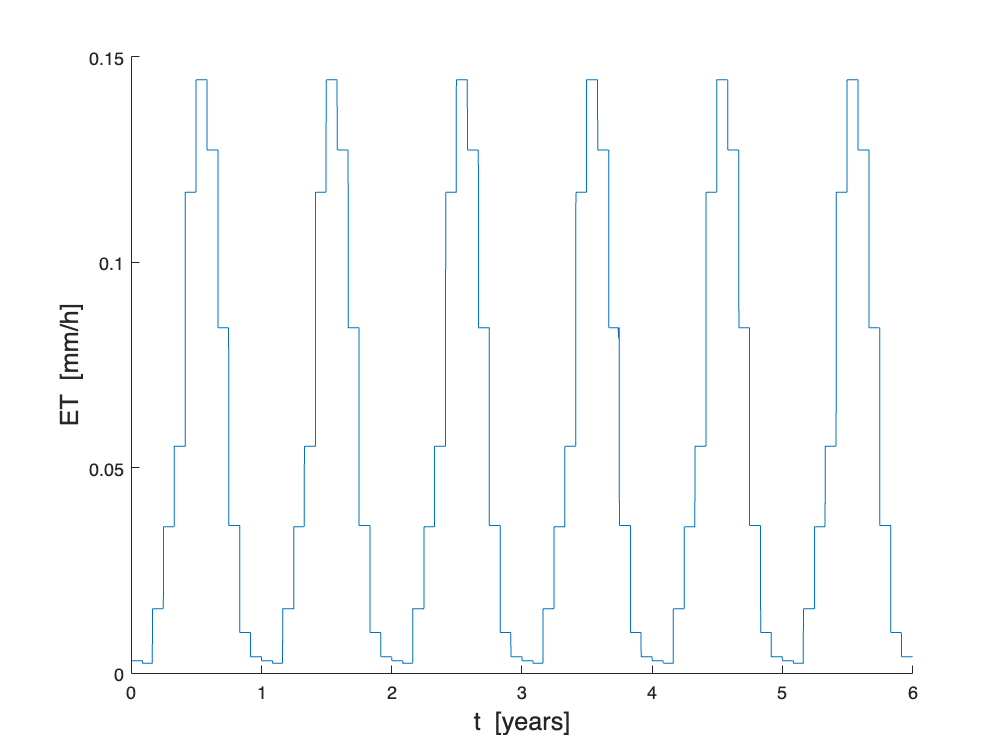

figure(8)                                          
plot((1:length(ET))/(365*24),ET);
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('ET  [mm/h]','FONTSIZE',14)   
box off

**Deliverable 3** 

Plot the time series of observed discharge and of the discharge as simulated by the hydrological model with the best fit parameters. 

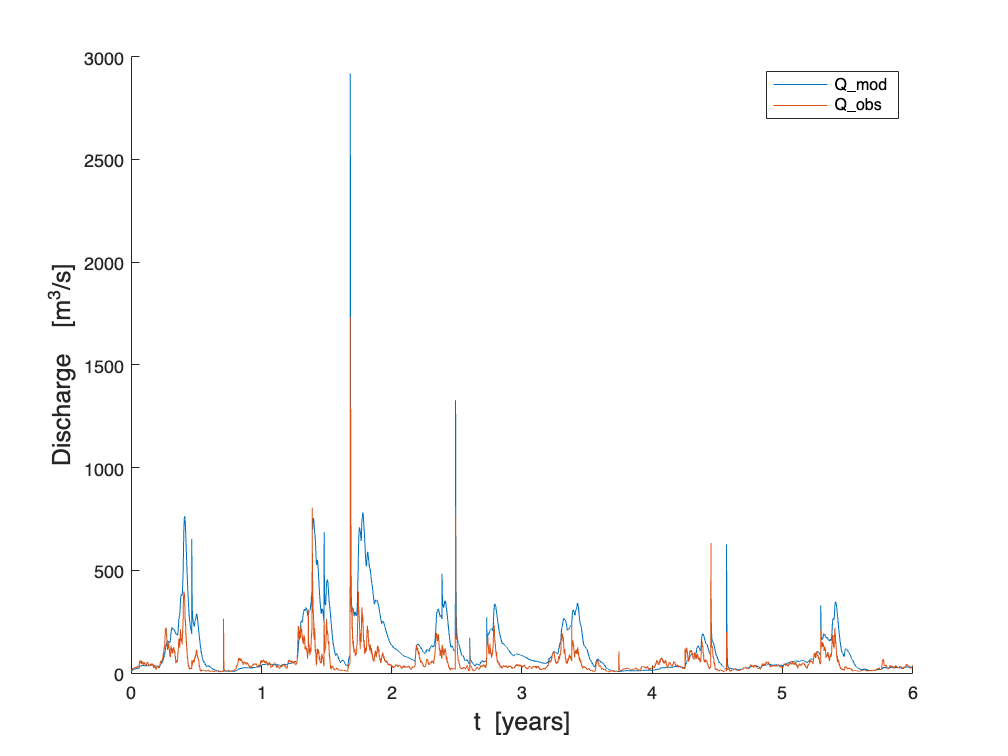

figure                                            
plot((1:length(Q_mod))/(365*24),Q_mod);
hold on
plot((1:length(Q_obs))/(365*24),Q_obs);
hold off
xlabel('t  [years]','FONTSIZE',14)                 
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)   
legend('Q\_mod', 'Q\_obs')
box off 

**Deliverable 4**

Plot Markov chains of the calibrated parameters and sequences of values of NS and TSA as a function of the number of iterations. Only plot accepted parameter sets. 

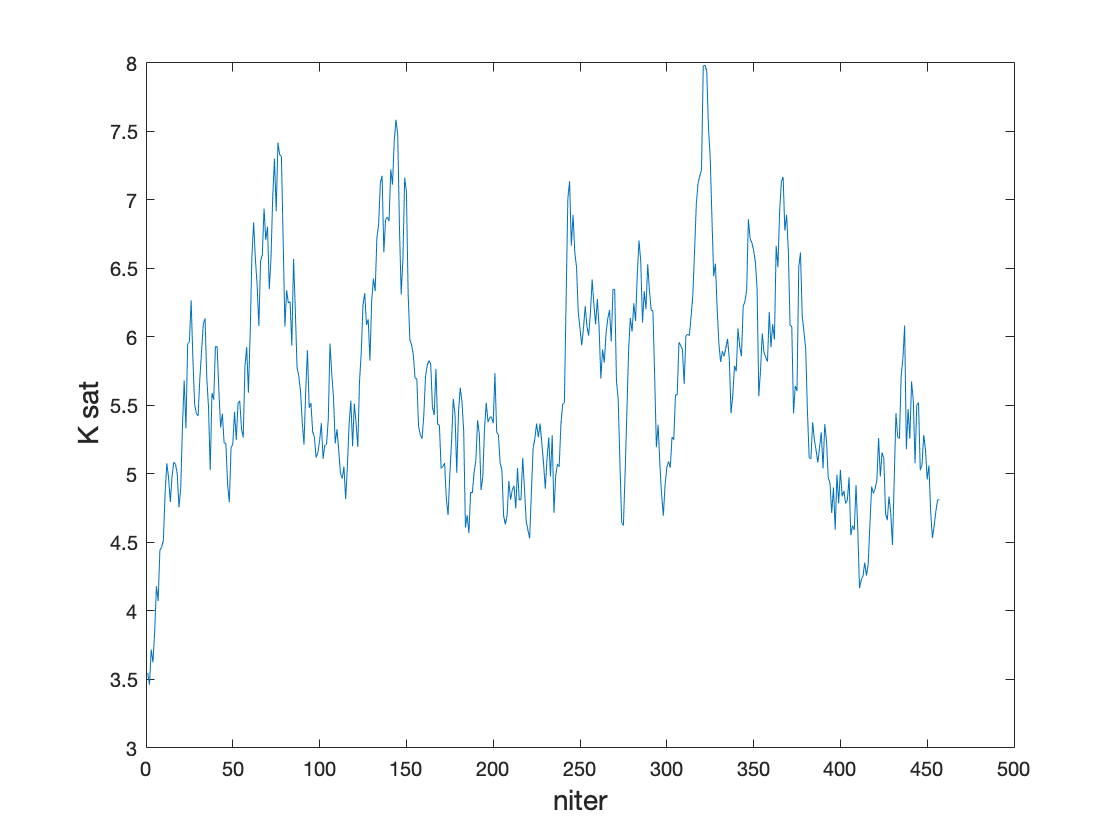


figure                                            
plot((1:length(ls)),ls(:,1));
xlabel('niter','FONTSIZE',14)                 
ylabel('K sat  ','FONTSIZE',14)   
box on 

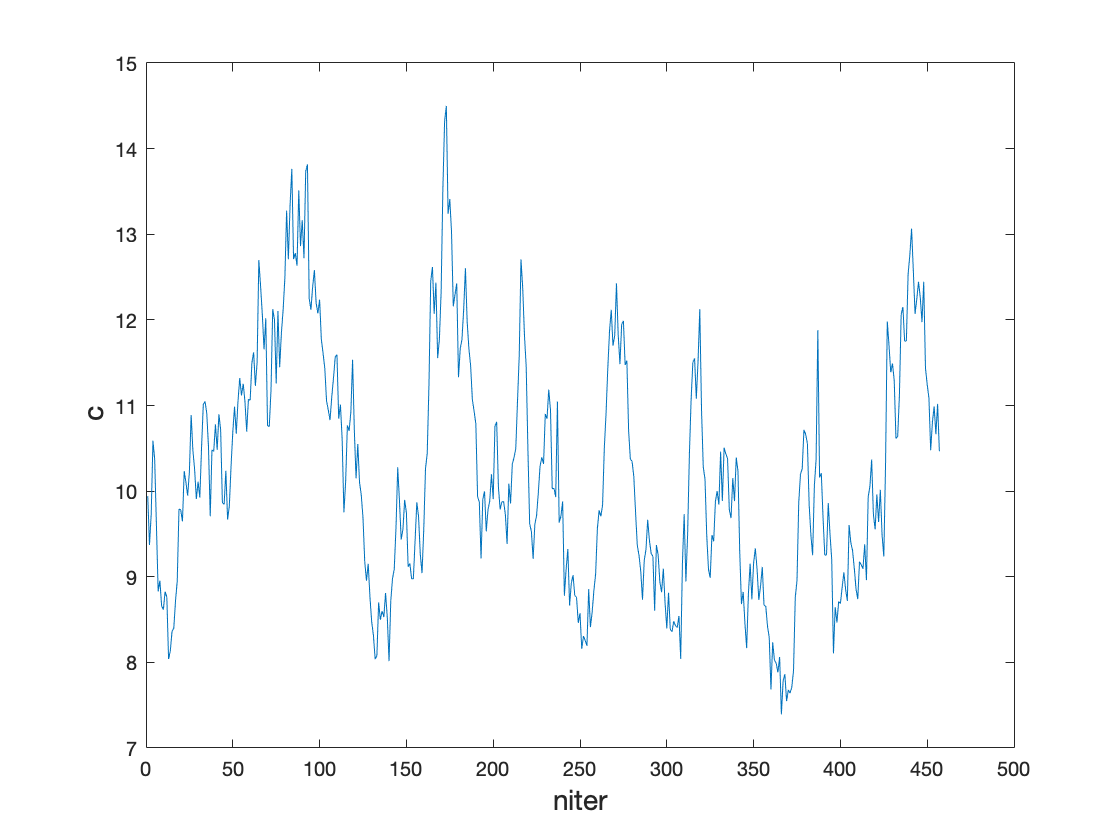

figure                                            
plot((1:length(ls)),ls(:,2));
xlabel('niter','FONTSIZE',14)                 
ylabel('c  ','FONTSIZE',14)   
box on 

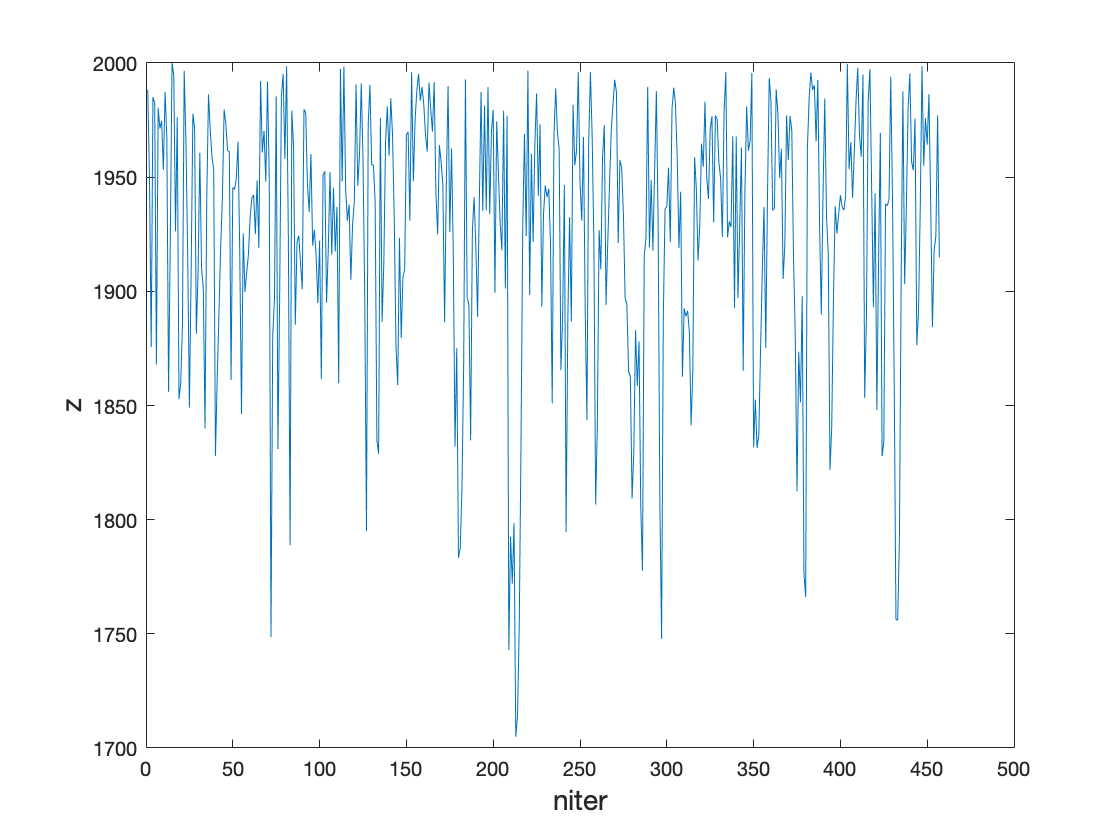

figure                                            
plot((1:length(ls)),ls(:,3));
xlabel('niter','FONTSIZE',14)                 
ylabel('z','FONTSIZE',14)   
box on 

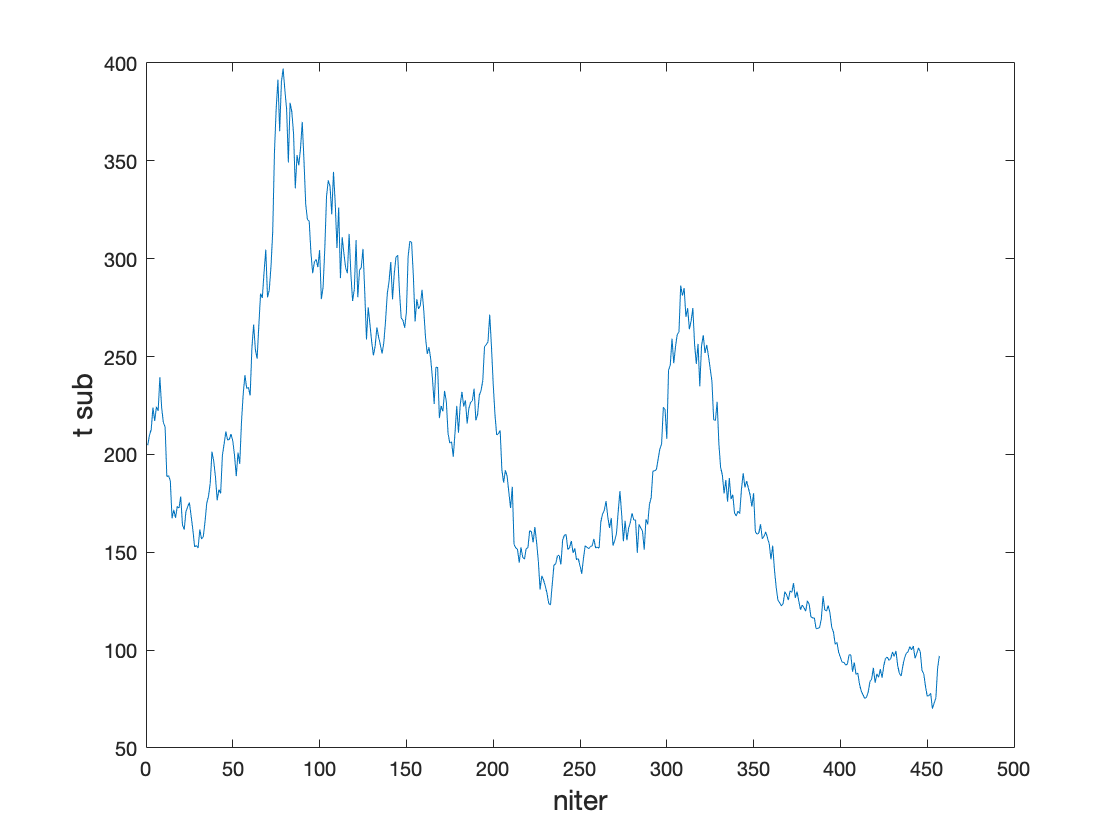

figure                                            
plot((1:length(ls)),ls(:,4));
xlabel('niter','FONTSIZE',14)                 
ylabel('t sub','FONTSIZE',14)   
box on 

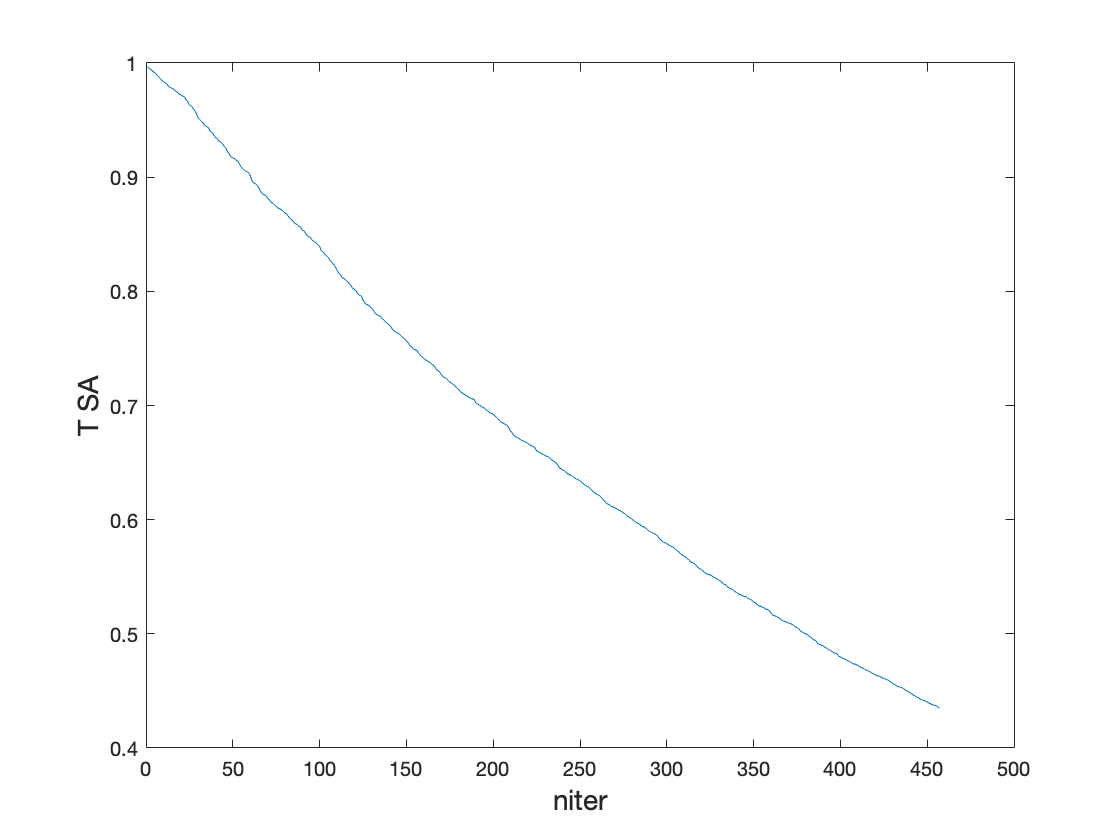


figure                                            
plot((1:length(T_SA)),T_SA);
xlabel('niter','FONTSIZE',14)                 
ylabel('T SA','FONTSIZE',14)   
box on 

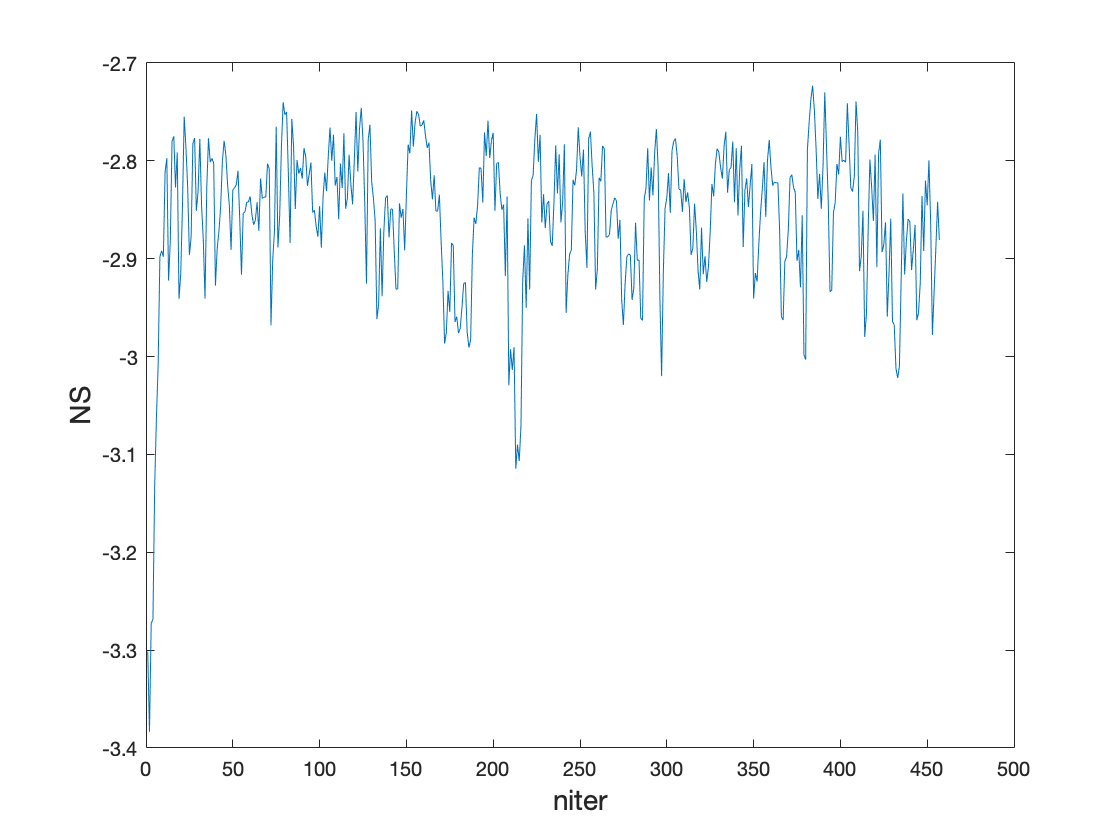

figure                                            
plot((1:length(NS)),NS);
xlabel('niter','FONTSIZE',14)                 
ylabel('NS','FONTSIZE',14)   
box on

## Simulated discharge sequence

Run the calibrated hydrological model forced by the generated rainfall and obtain the discharge time series that will constitute the input of the reservoir.

file = matfile("P_hourly.mat");
P_HOURLY = file.P_HOURLY;

Q_simulated = hydrological_model(P_HOURLY, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A, 1);

## Reservoir routing and flood control

%% Reservoir parameters
Cq_sluice = 0.6; %discharge coefficient sluice gate [-]
Cq_spill = 0.7;  %discharge coefficient spillway [-]
L = 140;         %spillway length [m]
p = 19;          %level of spillway with respect to the empty pool level [m]

### 1. Compute the minimum flow target Q347

sort_Q=sort(Q_simulated,'descend');
p_exceedence=(1:length(Q_simulated))/length(Q_simulated);
figure
semilogy(p_exceedence,sort_Q)
title('Discharge Duration Curve','FONTSIZE',14)
xlabel('fraction of the time equalled or exceeded','FONTSIZE',14)                   
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14) 
box off

Q347=sort_Q(find(p_exceedence>0.95,1,'first'));
hold on
plot([0 0.95],[Q347 Q347],'--r')
disp('The discharge that is exceeded 95% of the time is equal to'); Q_347=strcat(num2str(sort_Q(round(length(Q_simulated)*0.95))), ' m3/s')


### 2. Starting from the area rating curve, compute the volume rating curve (use trapezoidal approximation).

Determine the area rating curve

%area rating curve

level=area_rating_curve(:,1);          %"level": levels within the reservoir [m] above see level
level=level-level(1);                  %"level": levels with respect to the empty pool level (level(1))
lake_area=area_rating_curve(:,2);      %"lake_area": lake area corresponding to the "level" values


Determine the volume rating curve through the trapezoidal integration

%determination of the Volume rating curve (volume corresponding to the "level" values)
Volume=cumtrapz(level,lake_area);         %"Volume":volume corresponding to the "level" values


Plot them

%plot area and volume rating curve
figure
subplot(1,2,1)
plot(level,lake_area,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)        %insert label x axis
ylabel('Area  [m^{2}]','fontsize',12)     %insert label y axis
box off
subplot(1,2,2)
plot(level,Volume,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)
ylabel('Volume  [m^{3}]','fontsize',12)
box off

### 3. Assume a value for the maximum level for hydroelectric use (e.g. 15 m) and compute the corresponding volume.

level_max = 15 %[m]  % maximum level for hydroelectrical use
level_min = 609 -level(1) %[m]  % minimum level for hydroelectrical use
volume_max = Volume(level_max+1) %[m^3]

### 4. For each time step of integration (∆t = 1 hour)

%%% variable initialization  %%%

dt=1;                  %timestep of integration [h];
Q_lim = 100*3600  % limit discharge for floods [m^3/h] 
g = 9.81 % gravitational acceleration [m/s^2]


%%% vectors preallocation %%%

V=zeros(length(Q_simulated),1);           % volume time series
l=zeros(length(Q_simulated),1);           % level time series
sluice_A=zeros(length(Q_simulated),1);    % sluice gate opening time series
Qout=zeros(length(Q_simulated),1);        % outflowing dicharge time series
Q_HU=zeros(length(Q_simulated),1);        % discharge for hydropower time series
Q_WTP=zeros(length(Q_simulated),1);       % discharge to water treatment plant
Qg=zeros(length(Q_simulated),1);          % Sluice discharge

E=zeros(9,1);
p_flood=zeros(9,1);

%%% Initial conditions %%%

V(1)=level_volume(Volume,level,p);   %initial volume (level equal to the spillway level)
l(1)=p;  %[m]

% Computing initial sluice gate discharge

Q1_buffer = (V(1) + (Q_simulated(1)-Q_HU(1))*dt- volume_max)/dt;
Q2_buffer = min(Q_lim, Q1_buffer);
Qg(1)= max(Q347,Q2_buffer);  % [m^3/h]



for t= 2:dt:length(Q_simulated)

    l(t) = level_volume(Volume,level,V(t-1));  %reservoir level


    %%%  Computation of Q_HU [m^3/h] %%%

    ndays = idivide(t,24);   %get the number of days elapsed
    
    pump_start = ndays*24 + 6;
    pump_stop = ndays*24 +22;
    
    if t>=pump_start && t<=pump_stop && l(t)>level_min
        Q_HU(t) = Q_T; 
    else 
        Q_HU(t) = 0;
    end


    %%%  Sluice gate area computation %%%
    
    % computation of discharge through the gate 
    Q1_buffer = (V(t) + (Q_simulated(t)-Q_HU(t))*dt - volume_max)/dt;
    Q2_buffer = min(Q_lim,Q1_buffer);
    Qg(t)= max(Q347, Q2_buffer);  %[m^3/h]

    % computation of exit velocity applying energy equation between water
    % table in the reservoir and reservoir exit

    v_exit = sqrt(l(t)/(2*g)) *3600 %exit velocity [m/h]
    
    % Sluice gate area 

    sluice_A(t) = Qg(t)/v_exit;


    %%% Total output discharge computation %%%

    if l(t)<= p 
        Qout(t) = Cq_sluice * sluice_A(t) * sqrt(2*g*l(t));
    else
        Qout(t) = Cq_sluice * sluice_A(t) * sqrt(2*g*l(t)) + Cq_spill * L * sqrt(2*g*(l(t)-p)^3);
    end
    

    %%% Storage equation integration %%%

    dV = (Q_simulated(t) - Qout(t) - Q_HU(t)) * dt;
    V(t+1) = V(t) + dV;

end